# TPA 3 MPC Grupo 10

A contiunación se obtiene el modelo discrete en espacio de estados a partir del modelo de orden 6 obtenido en el TP1 (identificación)

close all; clc;
s = tf('s');

% addpath(genpath('...'));
% savepath

% modelo de orden 6
model_6 = 1.261e06/(s^6 + 75.11* s^5 + 1869* s^4 + 2.523e04* s^3 + 1.888e05* s^2 + 7.568e05* s + 1.26e06)


model_6 =
 
                                  1.261e06
  ------------------------------------------------------------------------
  s^6 + 75.11 s^5 + 1869 s^4 + 25230 s^3 + 188800 s^2 + 756800 s + 1.26e06
 
Continuous-time transfer function.
Model Properties


% model_6 = 10/(s*s+0.1*s+3);

[p, z] = pzmap(model_6);
high_freq_pole = abs(max(p));

% TIEMPO DE MUESTREO
Ts = round(1/(5*high_freq_pole), 3)

Ts = 0.0050


model_discrete = c2d(model_6, Ts)


model_discrete =
 
  2.594e-11 z^5 + 1.402e-09 z^4 + 7.044e-09 z^3 + 6.676e-09 z^2 + 1.194e-09 z + 1.984e-11
  ---------------------------------------------------------------------------------------
          z^6 - 5.647 z^5 + 13.28 z^4 - 16.64 z^3 + 11.72 z^2 - 4.397 z + 0.6869
 
Sample time: 0.005 seconds
Discrete-time transfer function.


[model_A, model_B, model_C, model_D] = tf2ss(model_discrete.Numerator{1}, model_discrete.Denominator{1});

Se verifican los modelos continuos y discretos comparando sus respuestas al escalón

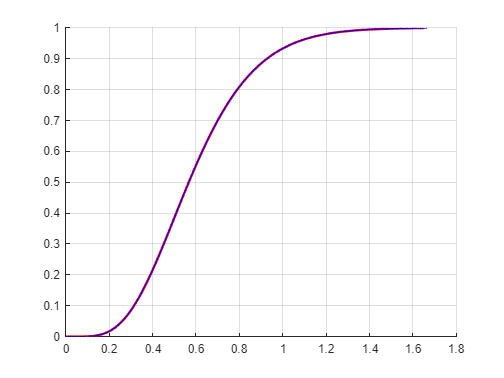

[cont_y, cont_t] = step(model_6);
[disc_y, disc_t] = step(model_discrete);

figure; hold on; grid on;
plot(cont_t, cont_y, 'r', 'LineWidth', 2);
plot(disc_t, disc_y, 'b', 'LineWidth', 1);

Ahora se obtiene el modelo en espacio de estados pero considerando variaciones en la entrada en de las muestras $\Delta U$(modelo incremental = inc_model)

A_expanded = [model_A, model_B; zeros(1, length(model_A)), ones(1, 1)];
B_expanded = [model_B; ones(1, 1)];
C_expanded = [model_C, zeros(1,1)];

inc_model = ss(A_expanded, B_expanded, C_expanded, 0, Ts)


inc_model =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7
   x1    5.647   -13.28    16.64   -11.72    4.397  -0.6869        1
   x2        1        0        0        0        0        0        0
   x3        0        1        0        0        0        0        0
   x4        0        0        1        0        0        0        0
   x5        0        0        0        1        0        0        0
   x6        0        0        0        0        1        0        0
   x7        0        0        0        0        0        0        1
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   1
 
  C = 
              x1         x2         x3         x4         x5         x6         x7
   y1  2.594e-11  1.402e-09  7.044e-09  6.676e-09  1.194e-09  1.984e-11          0
 
  D = 
       u1
   y1   0
 
Sample time: 0.005 seconds
Discrete-time state-space model.


Se cargan las matrices F y $\phi \;$

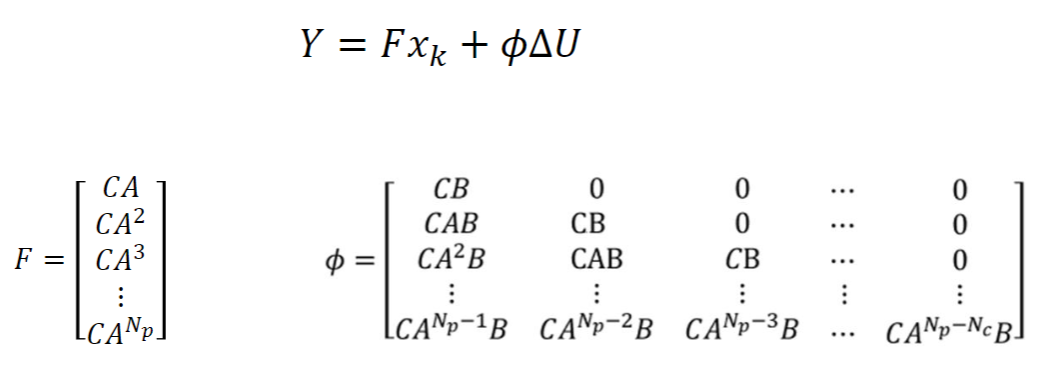

## Para calcular Np consideré que si Ts=0.1 y Tr=1.4 entonces entran 14 muestras hasta que se extinguen los transitorios

# IMPORTANTE: No se si lo anterior es cierto

Np = round(1.4/Ts);
Nc = 3;

% Esto genera F para un rango dinámico Np
F_mat = zeros(Np, length(A_expanded));
F_mat(1, :) = C_expanded*A_expanded;
for i = 2:Np
    F_mat(i, :) = F_mat(i-1, :)*A_expanded;
end
F_mat

F_mat =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0001   -0.0001    0.0000   -0.0000    0.0000



% Esto genera phi para un rango dinámico de Np y Nc
phi_mat = zeros(Np, Nc);
for j = 1:Nc
    for i = 1:Np
        if (i < j)
            phi_mat(i, j) = 0;
        elseif (i == j)
            phi_mat(i, j) = C_expanded*B_expanded;
        else
            phi_mat(i, j) = C_expanded*(A_expanded^(Np-j))*B_expanded;
        end
    end
end
phi_mat

phi_mat =     0.0000         0         0
  120.1274    0.0000         0
  120.1274  113.3405    0.0000
  120.1274  113.3405  107.3857
  120.1274  113.3405  107.3857
  120.1274  113.3405  107.3857
  120.1274  113.3405  107.3857
  120.1274  113.3405  107.3857
  120.1274  113.3405  107.3857
  120.1274  113.3405  107.3857


A continuación se calculan las entradas $\Delta U$de manera analítica

reference = 1;
states = zeros(length(A_expanded), 1);
ref_weight_mat = 0.1*eye(Nc);
Rs = ones(1, Np);
dU = ((((phi_mat')*phi_mat+ref_weight_mat)^(-1))*(phi_mat'))*(Rs*reference-F_mat*states)

dU =     0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    


Rs*reference

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


F_mat*states

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


(Rs*reference-F_mat*states)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 